# Atividade 07_03

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Detecção de bordas usando o LoG (função edge)

O “Laplaciano puro” é muito sensível ao ruído. Por isso, conforme comentamos, o operador baseado na derivada segunda utilizado para a detecção de bordas é o Laplaciano do Gaussiano (LoG), que incorpora no operador Laplaciano (derivada segunda) uma suavização através de uma função Gaussiana. Nesta a tividade, o objetivo é observar como o valor de sigma influencia a saída do detector de bordas baseado no LoG. Para isso adote o seguinte procedimento:

(i) Como imagem de entrada use a cameraman.tif ou outra, se preferir.

(ii) Entenda a sintaxe da função edge para o LoG, mostrada a seguir, e:

(a) o valor do limiar que atua na sensibilidade da detecção das passagens por zero deve ser mantido fixo, isto é, adote o mesmo valor de limiar para as 3 situações (b) abaixo;

(b) rode a detecção de borda para três valores diferentes de sigma.

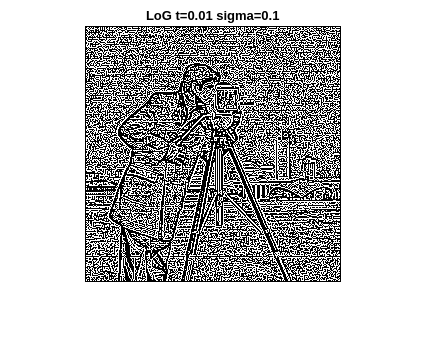

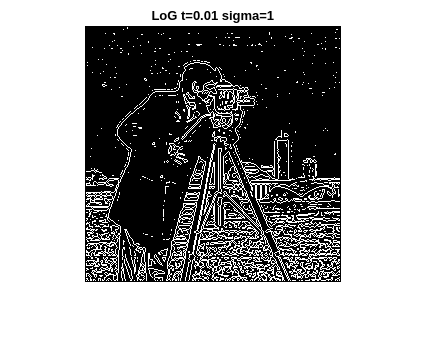

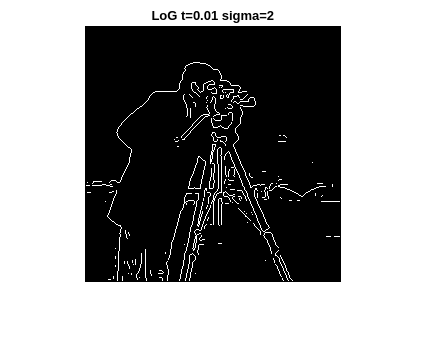

img = imread("cameraman.tif");

threshold = 0.01;
sigmas = [0.1 1 2];

for sigma = sigmas
    BW = edge(img, "log", threshold, sigma);

    figure, imshow(BW)
    title("LoG t=" + threshold + " sigma=" + sigma)
end